# **ABDULLAH AHMED**

#### **aa09303**

**TASK 1)**

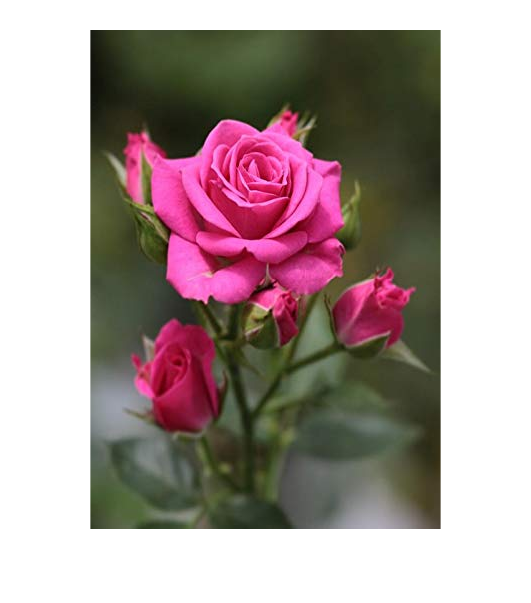

clc;
clear;
close all;

I = imread("flower.jpg");
% Convert to double precision
I = im2double(I);
% Display
figure;
imshow(I);

whos I;

  Name        Size                 Bytes  Class     Attributes

  I         500x351x3            4212000  double              



[R, G, B] = imsplit(I);
whos R;

  Name        Size               Bytes  Class     Attributes

  R         500x351            1404000  double              



W = 5;
h = ones(W) ./ W .^ 2;
Ravg = conv2(R, h, "same");
% Convolve G with h to blur the image
Gavg = conv2(G, h, "same"); %Write your code here
% Convolve B with h to blur the image
Bavg = conv2(B, h, "same"); %Write your code here
% Concatenate the three matrices to put together the color image
Iavg = cat(3, Ravg, Gavg, Bavg);
whos Iavg;

  Name        Size                 Bytes  Class     Attributes

  Iavg      500x351x3            4212000  double              



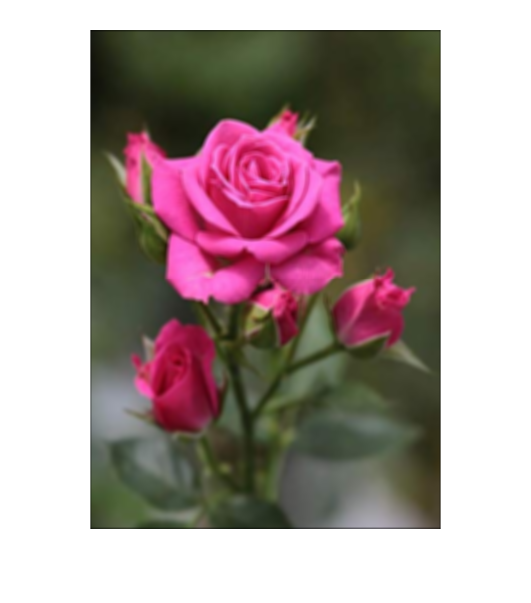

imshow(Iavg,[]);

**TASK 2)**

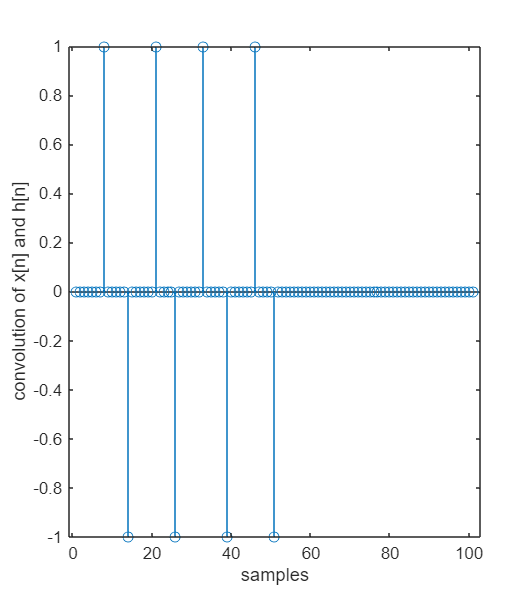

n = 0:50;
x_n = double((sin(0.5*n)+0.2) < 0);
impulse_n = n == 0;
impulse_n_1 = n == 1;

h_n = impulse_n - impulse_n_1;

y = conv(x_n, h_n);

stem(y);
ylabel("convolution of x[n] and h[n]");
xlabel("samples");

**TASK 3)**

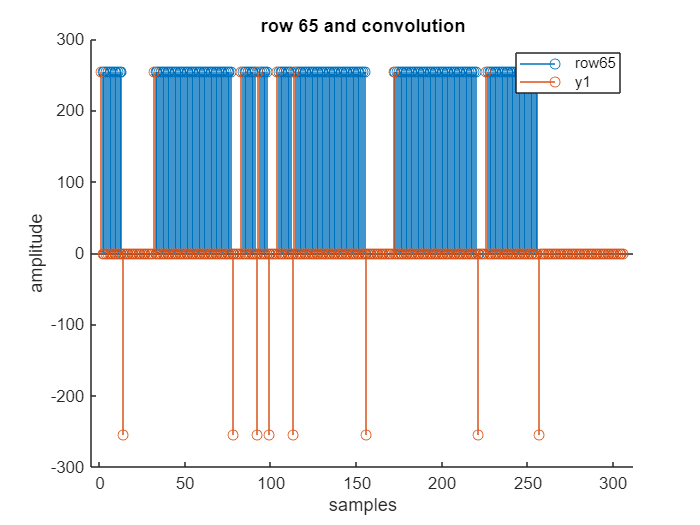

load echart.mat;
row_65 = echart(65,:);
y = conv(row_65, h_n);

figure;
hold on;

stem(row_65);
stem(y);

title("row 65 and convolution");
xlabel("samples");
ylabel("amplitude");
legend(["row65", "y1"]);
hold off;

**TASK 4)**

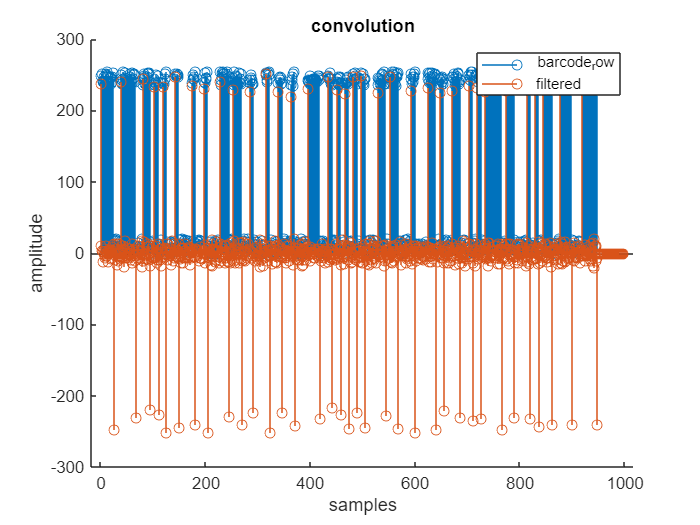

% 1)
barcode = imread("HP110v3.png");
row = barcode(65,:);
% 2)
filtered = conv(row, h_n);

figure;
hold on;

stem(row);
stem(filtered);

title("convolution");
xlabel("samples");
ylabel("amplitude");
legend(["barcode_row", "filtered"]);

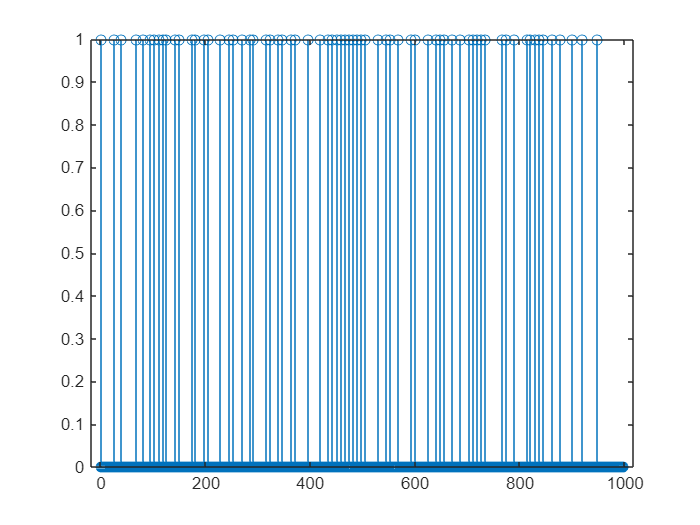

% 3)
% It can be because all the lines are not completely stright. Some have
% bumps

d_n = abs(filtered) >= 200;

figure;
stem(d_n);

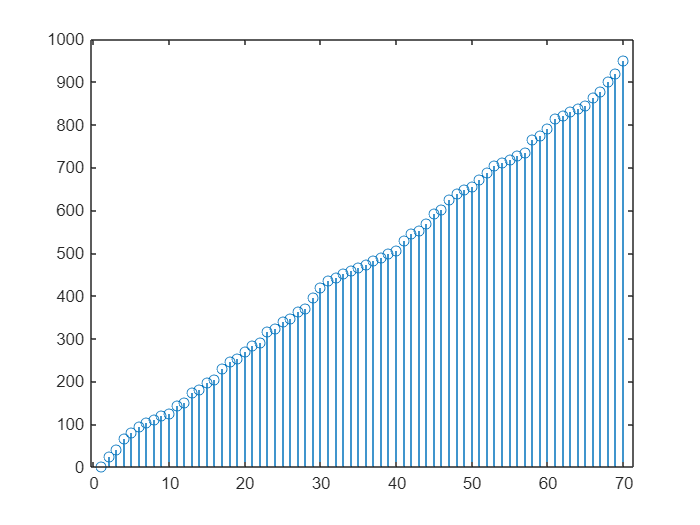

%4)
l_n = find(d_n);
delta_n = diff(l_n);

figure;
stem(delta_n);


